
$$y_{k+1}=y_k+hf(x_{k+1},y_{k+1})$$


clc,clear,close all


$$y(0)=1$$



$$y'(x,y)=y-\frac{2x}{y}$$


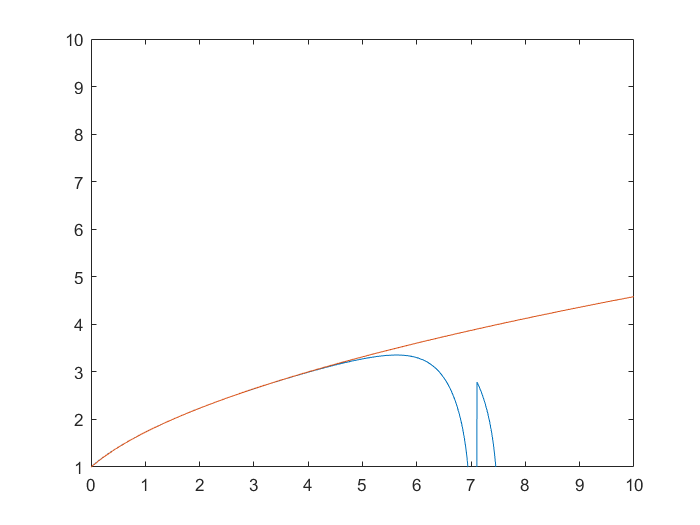

%% !!!!! 程序可能存在问题，误差有点大，但是不知道哪里有问题。不过也有可能没问题就是这个算法效果不好....

h = 0.00001;
a = 0;
b = 10;
y0 = 1;

x = a:h:b;
y = zeros(1,length(x));
y(1) = y0;

k=5;

for i = 1:length(x)-1
    yy = y(i) + (y(i)-2*x(i)/y(i))*h;
    for j = 1:k
        delta = y(i)-2*x(i+1)/yy;
        yy = y(i) + delta*h;
    end
    delta = y(i)-2*x(i+1)/yy;
    y(i+1) = y(i) + delta*h;
end

plot(x,y)

hold on 
syms x
fplot(sqrt(1+2*x))
xlim([a,b])
ylim([1,10])